## Assignment 02

clear all;
close all;
clc;

format short;

### 0. Introduction

We know that the distribution is an hyper-exponential one. From that we know that the moments are equal to:


$$E[X] = \frac{p_1}{\lambda_1} + \frac{1-p_1}{\lambda_2}$$



$$E[X^2] = 2 \left( \frac{p_1}{\lambda_1^2} + \frac{1-p_1}{\lambda_2^2} \right)$$



$$E[X^3] = 6 \left( \frac{p_1}{\lambda_1^3} + \frac{1-p_1}{\lambda_2^3} \right)$$


From this we can easily apply the *method of moments.*

Moreover the PDF function is:


$$f(t) = p_1 \lambda_1e^{-\lambda_1 t} + (1-p_1)\lambda_2 e^{-\lambda_2 t}$$


And the CDF function is:


$$F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$$


### 1. Load data

T = readtable('data.xlsx');
T.Properties.VariableNames = {'data'};
data = T.data

data = 	1.0e+03 *

    0.0831
    0.0956
    0.1975
    0.0962
    0.4626
    0.0375
    0.4831
    0.1537
    0.0000
    0.0565


N = height(T)

N = 80

### 2. Compute stats

#### 2.1 Moments

First moment

x_1 = (1/N)*sum(data)

x_1 = 220.1726

Second moment

x_2 = (1/N)*sum(data.^2)

x_2 = 1.0562e+05

Third moment

x_3 = (1/N)*sum(data.^3)

x_3 = 7.2900e+07

Fourth moment

x_4 = (1/N)*sum(data.^4)

x_4 = 5.9846e+10

#### 2.2 Compute $\sigma^2$, $\sigma$ and $C_v$

Mean (used for the $C_v$ computation)

mu = mean(data)

mu = 220.1726

Variance

sigma_2_unbiased = var(data)

sigma_2_unbiased = 5.7866e+04

sigma_2 = x_2 - x_1^2

sigma_2 = 5.7143e+04

Standard deviation

sigma_unbiased = sqrt(sigma_2_unbiased)

sigma_unbiased = 240.5536

sigma = sqrt(sigma_2)

sigma = 239.0454

Coefficient of variation

cv = sigma / mu

cv = 1.0857

#### 2.3 Skewness $\gamma$

The skewness is defined as:


$$\gamma = E \left[ \left( \frac{X-\mu}{\sigma} \right)^3 \right] =
\frac{E[X^3] - 2\mu\sigma^2 - \mu^3}{\sigma^3}$$


gamma = (x_3 - 2*mu*sigma_2 - mu^3) ./ (sigma^3)

gamma = 2.7134

gamma_unbiased = skewness(data)

gamma_unbiased = 1.7924

#### 2.4 Kurtois $\beta$


$$\beta= E \left[ \left( \frac{X-\mu}{\sigma} \right)^4 \right] - 3=
\frac{E[(X - \mu)^4]}{\sigma^4} - 3$$


beta = ((1/N) * sum((data - mu).^4)) ./ (sigma^4) - 3

beta = 2.9149

%beta_unbiased = kurtosis(data) - 3

### 3. Fitting

#### 3.1 Maximum Likelihood method

First we have to compute the likelihood function. So, first let's hyphotesize some valure for $\lambda_1, \lambda_2$ and $p_1$.


$$\lambda_1=0.001$$



$$\lambda_2=0.001$$



$$p_1=0.5$$


l1 = 0.001;
l2 = 0.001;
p1 = 0.5;

So, we have to compute $log(f(t))$

log_pdf = @(data,p1,l1,l2) log10(p1*l1*exp(-l1*data) + (1-p1)*l2*exp(-l2*data));
lpdf = log_pdf(data,p1,l1,l2)

lpdf =    -3.0361
   -3.0415
   -3.0858
   -3.0418
   -3.2009
   -3.0163
   -3.2098
   -3.0668
   -3.0000
   -3.0245


log_likehood = sum(lpdf)

log_likehood = -247.6496

Let's now pass to the maximization procedure:

params = mle(data,'logpdf',log_pdf,'start',[p1,l1,l2], 'Lowerbound', [0, 0, 0], 'Upperbound', [1, 0.1, 0.1])

params =     0.6438    0.0035    0.0092


Let's evaluate the fit:

p1 = params(1)

p1 = 0.6438

l1 = params(2)

l1 = 0.0035

l2 = params(3)

l2 = 0.0092

fitted_log_likelihood = sum(log_pdf(data,p1,l1,l2))

fitted_log_likelihood = -221.8616

Approximating CDF:

sorted_data = sort(data)

sorted_data = 	1.0e+03 *

    0.0000
    0.0091
    0.0092
    0.0096
    0.0172
    0.0173
    0.0242
    0.0271
    0.0282
    0.0302


t = 1/80:1/80:1

t =     0.0125    0.0250    0.0375    0.0500    0.0625    0.0750    0.0875    0.1000    0.1125    0.1250    0.1375    0.1500    0.1625    0.1750    0.1875    0.2000    0.2125    0.2250    0.2375    0.2500    0.2625    0.2750    0.2875    0.3000    0.3125    0.3250    0.3375    0.3500    0.3625    0.3750    0.3875    0.4000    0.4125    0.4250    0.4375    0.4500    0.4625    0.4750    0.4875    0.5000    0.5125    0.5250    0.5375    0.5500    0.5625    0.5750    0.5875    0.6000    0.6125    0.6250


figure();
plot(sorted_data, t, 'LineWidth', 2);
grid on;
hold on;

Let's now compare it with the analytical $F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$:

F = @(t) 1 - p1*exp(-l1*t) - (1-p1)*exp(-l2*t);
cdf_data = F(sorted_data)

cdf_data =     0.0002
    0.0491
    0.0495
    0.0519
    0.0904
    0.0907
    0.1242
    0.1378
    0.1428
    0.1516


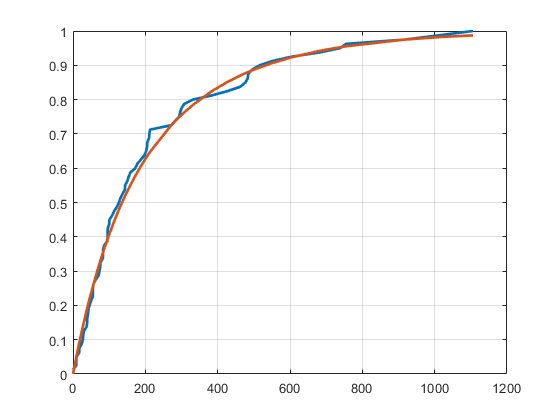

plot(sorted_data, cdf_data, 'LineWidth', 2);

%ylim([0,1]);
hold off;